# OFDM/QPSK変復調システム

前提条件

- AWGN通信路

- SN比: 0dB

- 帯域幅: 25Hz

- 搬送波周波数: 50Hz

- サンプリング周波数: 1kHz

- FFT点数: 64

- サブキャリア数: 52

## ワークスペースの初期化

clear
close all
clc

## 図のフォント設定

set(0, 'defaultAxesFontSize', 14);
set(0, 'defaultAxesFontName', 'times');
set(0, 'defaultTextFontSize', 14);
set(0, 'defaultTextFontName', 'times');

## パラメータの設定

BANDWIDTH = 25;
CARRIER_FREQ = 50;
MULTIPLE_LEVEL = 4;

snRatio = 0;

samplingFreq = 20*CARRIER_FREQ;
samplingPeriod = 1/samplingFreq;

nIFFT = 64;
nSubcarriers = 52;
timePeriodUseful = nIFFT/BANDWIDTH;
timePeriod = timePeriodUseful/nIFFT;
cyclicPrefix = 0;
bitsPerSymbol = log2(MULTIPLE_LEVEL);
nBits = bitsPerSymbol*nSubcarriers;

filterSpan = 6;
samplesPerSymbol = floor(timePeriod/samplingPeriod);
filterDA = rcosdesign(0.5, filterSpan, samplesPerSymbol, 'sqrt');
filterDelay = mean(grpdelay(filterDA))*((samplesPerSymbol-filterSpan/2)/samplesPerSymbol);

t = 0:1/samplingFreq:timePeriod-1/samplingFreq;

## 入力ビット列の確認

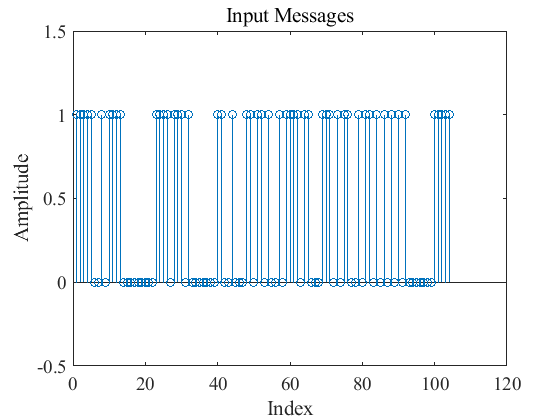

rng('shuffle');
messages = randi([0 1], 1, nBits);

stem(messages)
ylim([-0.5 1.5])
title('Input Messages')
xlabel('Index')
ylabel('Amplitude')

## 変調シンボル列の確認

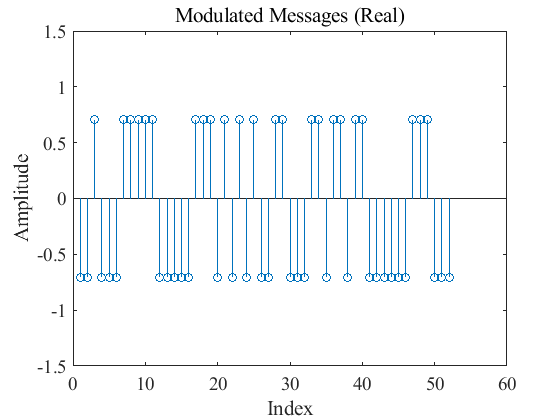

infoBinaryTilde = reshape(messages, [bitsPerSymbol,nSubcarriers]);
infoBinary = infoBinaryTilde';
infoDecimal = bi2de(infoBinary, 'left-msb');
infoModulated = pskmod(infoDecimal, MULTIPLE_LEVEL, pi/MULTIPLE_LEVEL, 'gray');

stem(real(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

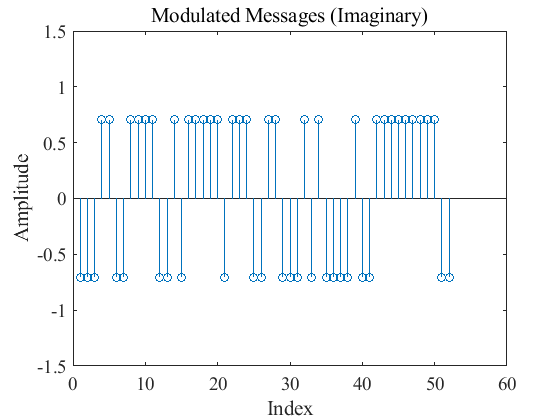

stem(imag(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## 離散時間OFDM信号の確認

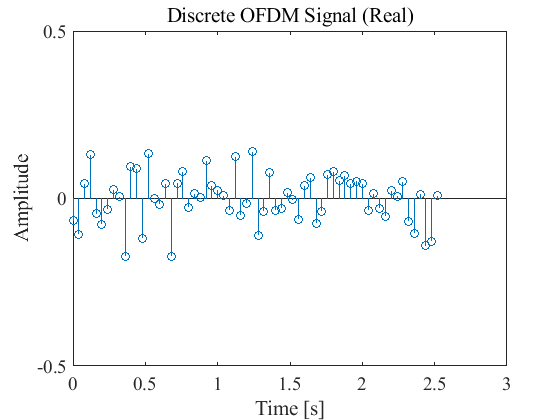

L = size(infoModulated, 1);
info = zeros(nIFFT, 1);
info(2:(L/2)+1,1) = infoModulated(1:(L/2),1).';
info((nIFFT-((L/2)-1)):nIFFT,1) = infoModulated(((L/2)+1):L,1).';

ofdmDiscrete = ifft(info, nIFFT);

stem((0:timePeriod:(length(ofdmDiscrete)-1)*timePeriod), real(ofdmDiscrete))
ylim([-0.5 0.5])
title('Discrete OFDM Signal (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

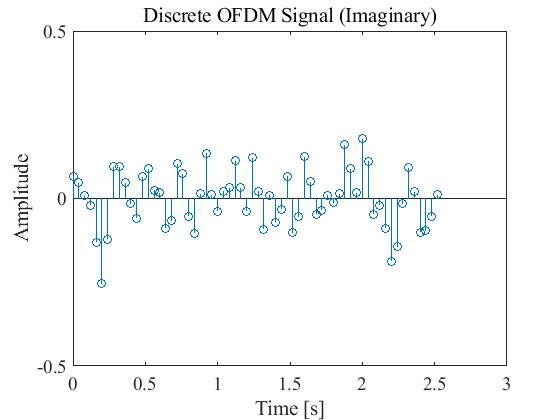

stem((0:timePeriod:(length(ofdmDiscrete)-1)*timePeriod), imag(ofdmDiscrete))
ylim([-0.5 0.5])
title('Discrete OFDM Signal (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## 連続時間OFDM信号の確認

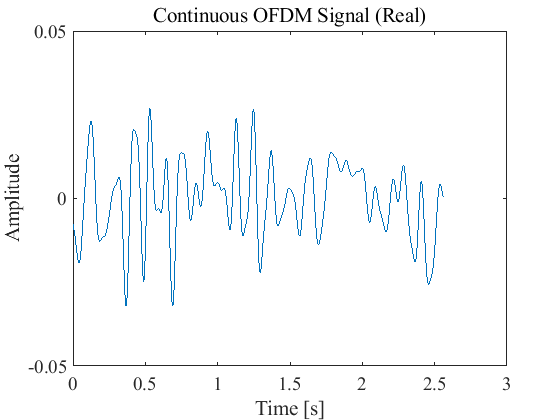

tt = 0:1/samplingFreq:length(ofdmDiscrete)*timePeriod-1/samplingFreq;

ofdmSignalContinuousTilde = upfirdn(ofdmDiscrete.', filterDA, samplesPerSymbol);
ofdmSignalContinuousTilde(1:filterDelay) = [];
ofdmSignalContinuous = ofdmSignalContinuousTilde(1:length(tt));

plot(tt, real(ofdmSignalContinuous))
ylim([-0.05 0.05])
title('Continuous OFDM Signal (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

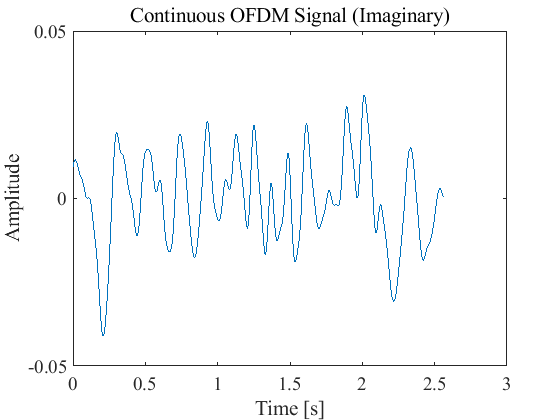

plot(tt, imag(ofdmSignalContinuous))
ylim([-0.05 0.05])
title('Continuous OFDM Signal (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## OFDM信号の確認

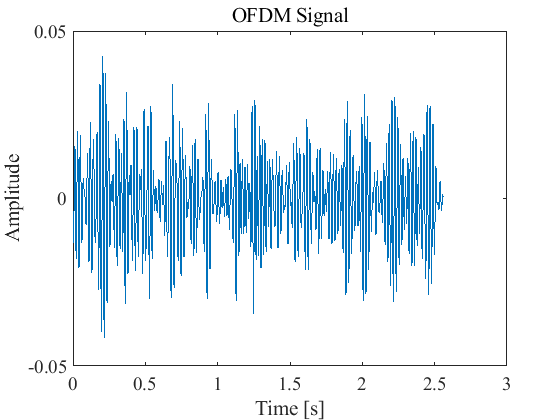

ofdmSignalTilde = ofdmSignalContinuous.*exp(1i*2*pi*CARRIER_FREQ*tt);

ofdmSignal = real(ofdmSignalTilde);

plot(tt, ofdmSignal)
ylim([-0.05 0.05])
title('OFDM Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 雑音印加後の信号確認

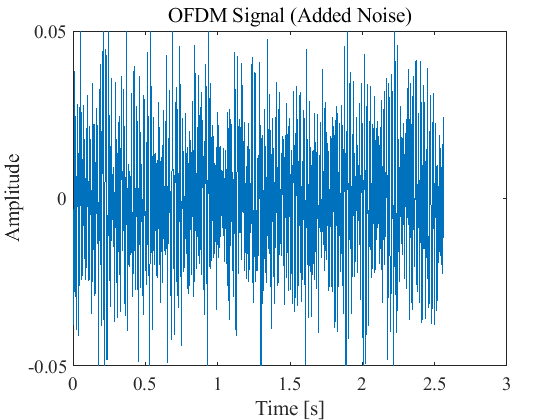

rng('shuffle')
signalAddedNoise = awgn(ofdmSignal, snRatio, 'measured');  % signalAddedNoise = ofdmSignal;

plot(tt, signalAddedNoise)
ylim([-0.05 0.05])
title('OFDM Signal (Added Noise)')
xlabel('Time [s]')
ylabel('Amplitude')

## 受信側LPF通過後の信号確認

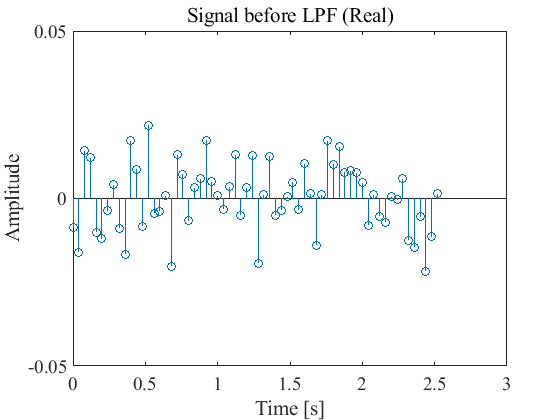

signalLPF = zeros(1, size(ofdmDiscrete,2));
for k = 1:length(ofdmDiscrete)
    signalLPF(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*exp(-1i*2*pi*CARRIER_FREQ*t))*(2/(timePeriod*samplingFreq));
end

stem((0:timePeriod:(length(ofdmDiscrete)-1)*timePeriod), real(signalLPF))
ylim([-0.05 0.05])
title('Signal before LPF (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

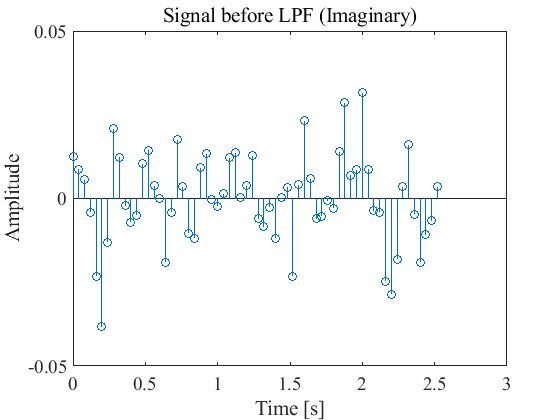

stem((0:timePeriod:(length(ofdmDiscrete)-1)*timePeriod), imag(signalLPF))
ylim([-0.05 0.05])
title('Signal before LPF (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## 復調シンボル列の確認

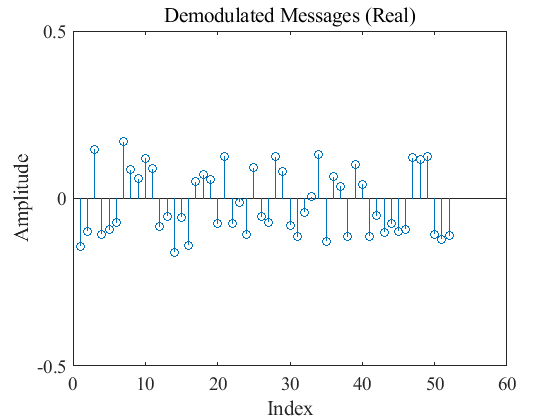

receivedInfoTilde = signalLPF.';
receivedInfo = fft(receivedInfoTilde, nIFFT);
receivedInfoModulated = zeros(nSubcarriers, 1);
receivedInfoModulated(1:(L/2),1) = receivedInfo(2:(L/2)+1,1);
receivedInfoModulated(((L/2)+1):L,1) = receivedInfo((nIFFT-((L/2)-1)):nIFFT,1);

stem(real(receivedInfoModulated))
ylim([-0.5 0.5])
title('Demodulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

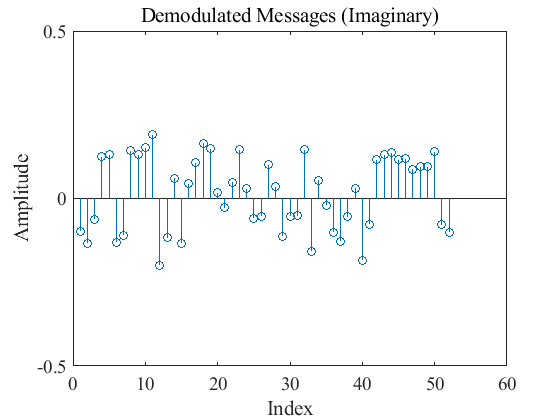

stem(imag(receivedInfoModulated))
ylim([-0.5 0.5])
title('Demodulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## 出力ビット列の確認

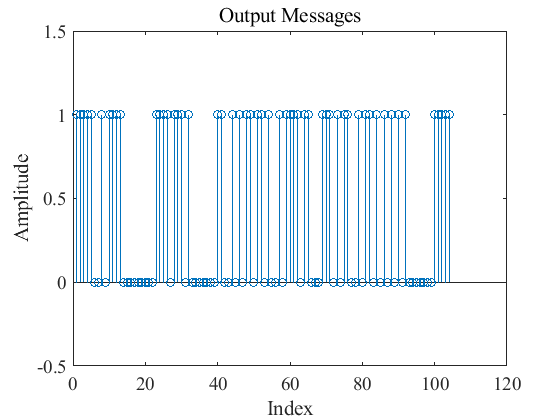

receivedInfoDecimal = pskdemod(receivedInfoModulated, MULTIPLE_LEVEL, pi/MULTIPLE_LEVEL, 'gray');
receivedInfoBinary = de2bi(receivedInfoDecimal, bitsPerSymbol, 'left-msb');
recievedMessagesTilde = receivedInfoBinary';
recievedMessages = recievedMessagesTilde(:)';

stem(recievedMessages)
ylim([-0.5 1.5])
title('Output Messages')
xlabel('Index')
ylabel('Amplitude')

## ビット誤り率の確認

bitErrorRate = biterr(messages, recievedMessages)/length(messages)

bitErrorRate = 0.0096